# Show Productive Structure Demo

Show the Productive Structure Info and the Productive Diagrams  

#### Read Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
data=ReadDataModel(file);

#### Get the Productive Structure Tables

res=ProductiveStructure(data,'Show',true);

Flows Definition Table

  Id Key   From     To       Type      
————————————————————————————————————————
   1 B1    BLR_P1   TRB_F1   INTERNAL  
   2 B2    TRB_F1   CND_F1   INTERNAL  
   3 B3    CND_F1   PMP_P1   INTERNAL  
   4 B4    PMP_P1   BLR_P1   INTERNAL  
   5 B5    CND_F2   VEXP_F1  INTERNAL  
   6 B6    VEXP_F1  EVAP_F1  INTERNAL  
   7 B7    EVAP_F1  CMP_P1   INTERNAL  
   8 B8    CMP_P1   CND_F2   INTERNAL  
   9 WT    TRB_P1   GEN_F1   INTERNAL  
  10 WC    GEN_F1   CMP_F1   INTERNAL  
  11 WP    GEN_P1   PMP_F1   INTERNAL  
  12 QBLR  ENV_R1   BLR_F1   RESOURCE  
  13 QEVP  EVAP_P1  ENV_O1   OUTPUT    
  14 WN    GEN_P1   ENV_O2   OUTPUT    
  15 QEXP  VEXP_P1  ENV_W1   WASTE     
  16 QCND  CND_P1   ENV_W2   WASTE     


Productive Groups Definition Table

  Id Key      Definition  Type      
—————————————————————————————————————
   1 BLR_F1   QBLR        FUEL      
   2 BLR_P1   B1-B4       PRODUCT   
   3 TRB_F1   B1-B2       FUEL      
   4 TRB_P1   WT          PRODU

#### Show Flows Diagram

Get the the productive diagrams by means of `ProductiveDiagram` function, use the option `SaveAs `to save in excel format the adjacency tables, and shows the Flows Diagram (fat) using the `ShowGraph` function

dg=ProductiveDiagram(data,'SaveAs','rorc_pd.xlsx');

INFO: cStatusLogger. File rorc_pd.xlsx has been saved


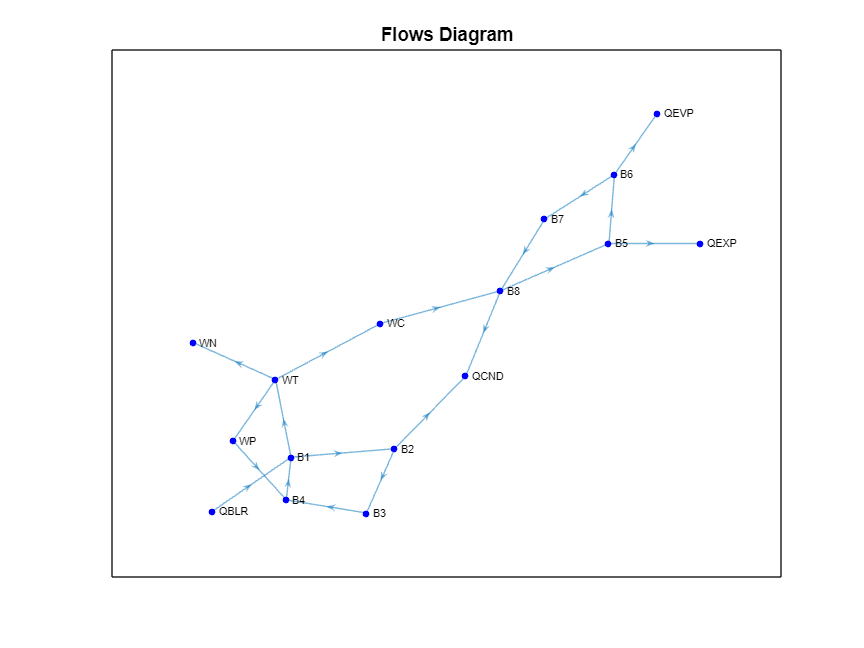

ShowGraph(dg,'Graph','fat');